tic
simplified_rev = rev("SimplifiedAgg.stl");
input_fabrics = simplified_rev.compute_input_fabrics();
toc

Elapsed time is 3.200774 seconds.


tic
images = simplified_rev.take_slice_images(20, 256, 0.1, true);
toc

Elapsed time is 119.688284 seconds.


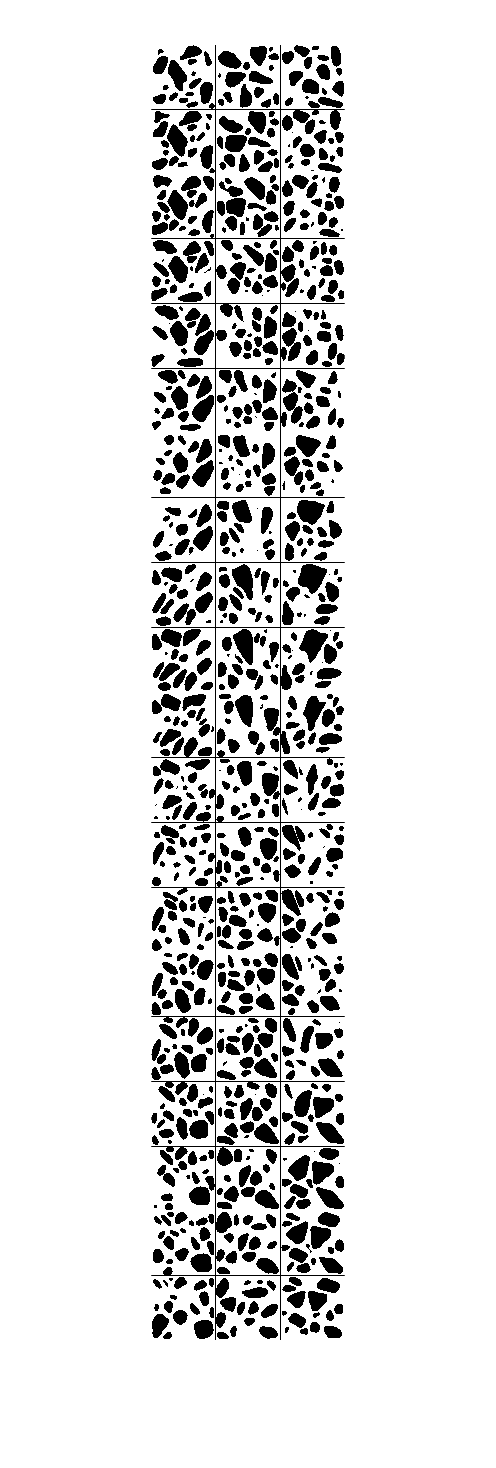

figure;
imshow(images)

imwrite(images, "stack_images.png")

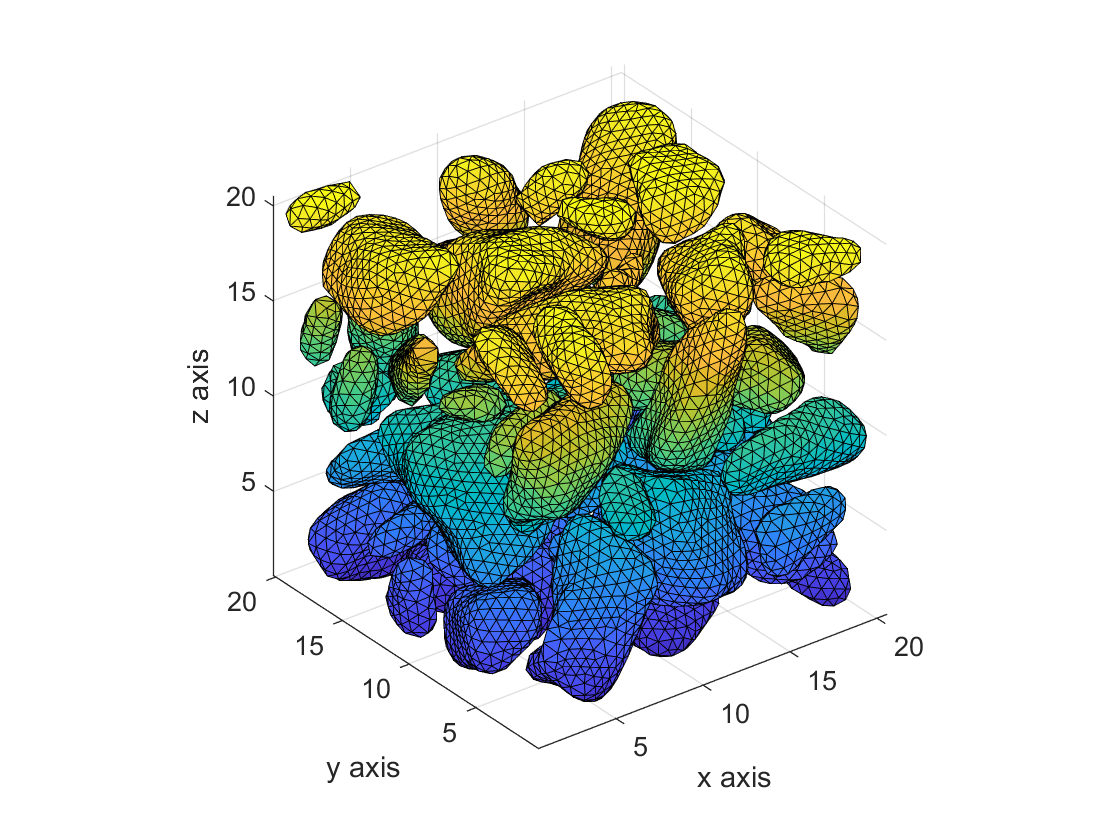

figure
trisurf(simplified_rev.TR);
xlabel("x axis");
ylabel("y axis");
zlabel("z axis");
axis equal